# Homework 3

**Sebastian Aguilera Novoa**

## **1. Limite on an Optimization Problem**

Given a matrix $J \in \mathbb{R}^{m\times n}$ and a matrix $Q \in \mathbb{R}^{n\times n}$ symmetric defined positive $Q \succ 0$, a vector of measures $\eta \in \mathbb{R}^m$ and a point $\overline{x}\in \mathbb{R}$, calculate the limite

In order to calculate this limit, the function$f(x)$ is defined to find its minimum value using the derivative


$$f(x)=\frac{1}{2} ||\eta-Jx||^2_2 + \frac{\alpha}{2} (x-\overline{x})^T Q(x-\overline{x}) = \frac{1}{2} (\eta-Jx)^T(\eta-Jx) + \frac{\alpha}{2} (x-\overline{x})^T Q(x-\overline{x})  \\
=  \frac{1}{2} (\eta^T \eta -x^TJ^T \eta -  \eta^T J x + x^TJ^T J x) + \frac{\alpha}{2}(x-\overline{x})^T Q(x-\overline{x})  \\
=  \frac{1}{2} (\eta^T \eta -2 J^T \eta x + x^TJ^T J x) + \frac{\alpha}{2} (x-\overline{x})^T Q(x-\overline{x}) \\
\nabla f(x) =  - J^T \eta + J^T J x +  \alpha Q(x-\overline{x})  \\
\nabla^2 f(x) =  J^T J + \alpha Q \succ 0$$


then, to find the minimum we have to solve $\nabla f(x) = 0$


$$\nabla f(x) =  - J^T\eta  + J^T J x +  \alpha Q(x-\overline{x})  =  - J^T \eta  + J^T J x +  \alpha Q x-\alpha 
 \overline{x}Q \overline{1} = 0\\
(J^T J+\alpha Q) x = J^T \eta+ \alpha \overline{x}Q \overline{1}\\
\Rightarrow \quad  x(\alpha) =(J^T J+\alpha Q)^{-1} (J^T \eta + \alpha \overline{x}Q\overline{1})$$


here $\overline{1} \in \mathbb{R}^n$ is a vector of ones. Using SVD decomposition$J = U \Sigma V^T$,with $U \in \mathbb{R}^{m\times m}, \Sigma\in \mathbb{R}^{m\times n}, V^T\in \mathbb{R}^{n\times n}$ 


$$J^T J+\alpha Q = V \Sigma^T U^T U \Sigma V^T + \alpha Q = V \Sigma^T \Sigma V^T + \alpha Q $$


descomposing $Q$ in terms of $V$, $Q = U' \Sigma' V^T$ since $Q$ is square then $U',\Sigma',V^T \in \mathbb{R}^{n \times n}$


$$J^T J+\alpha Q  = V \Sigma^T \Sigma V^T + \alpha U' \Sigma' V^T \;   = (V \Sigma^T \Sigma + \alpha  U' \Sigma'  )V^T = (V \Sigma^T \Sigma + \alpha V V^T U' \Sigma'   )V^T\\
J^T J+\alpha Q = V( \Sigma^T \Sigma + \alpha V^T U' \Sigma'   )V^T$$


calculating the inverse


$$(J^T J+\alpha Q )^{-1}= (V( \Sigma^T \Sigma + \alpha V^T U' \Sigma'  )V^T))^{-1} = (V^T)^{-1}( \Sigma^T \Sigma + \alpha V^T U' \Sigma'  )^{-1}V^{-1}\\
= V( \Sigma^T \Sigma + \alpha V^T U' \Sigma'  )^{-1}V^{T} = V( \Sigma^T \Sigma + \alpha W \Sigma'  )^{-1}V^{T}$$


writing in matricial form and defining $W = V^T U', W \in \mathbb{R}^{n\times n}$


$$(J^T J+\alpha Q)^{-1}=V\; \pmatrix{\sigma_1^2+\alpha W_{1,1} \sigma'_1 & 0 & \cdots&&&0\cr
0 & \sigma_2^2+\alpha W_{2,2} \sigma'_2 & 0 & \cdots  & \cdots& 0 \cr
 \vdots &  \cdots &  \ddots &  \cdots & \cdots  & \vdots \cr
0 & \cdots &\cdots  & \sigma_r^2+\alpha W_{r,r} \sigma'_r & \cdots & 0 \cr
 \vdots &  \vdots &  \vdots &  \vdots & \vdots   \cr
0 &0 & \cdots& \cdots & \alpha W_{n-1,n-1} \sigma'_{n-1}  & 0\cr
0 & 0 & \cdots& \cdots& \cdots & \alpha W_{n,n} \sigma'_n
}^{-1} \; V^T$$



$$(J^T J+\alpha Q)^{-1}= V\; \pmatrix{\frac{1}{\sigma_1^2+\alpha W_{1,1} \sigma'_1} & 0 & \cdots&&&0\cr
0 & \frac{1}{\sigma_2^2+\alpha W_{2,2} \sigma'_2} & 0 & \cdots  & \cdots& 0 \cr
 \vdots &  \cdots &  \ddots &  \cdots & \cdots  & \vdots \cr
0 & \cdots &\cdots  & \frac{1}{\sigma_r^2+\alpha W_{r,r} \sigma'_r} & \cdots & 0 \cr
 \vdots &  \vdots &  \vdots &  \vdots & \vdots   \cr
0 &0 & \cdots& \cdots & \frac{1}{\alpha W_{n-1,n-1} \sigma'_{n-1}}  & 0\cr
0 & 0 & \cdots& \cdots& \cdots & \frac{1}{\alpha W_{n,n} \sigma'_n}
}\; V^T$$


now let's calculate the product $(J^T J+\alpha Q)^{-1} (J^T \eta + \alpha \overline{x}Q) 
$


$$
J^T \eta + \alpha \overline{x}Q \overline{1} = V \Sigma^T U^T \eta + \alpha \overline{x} U' \Sigma' V^T \;\overline{1} = V \Sigma^T U^T \eta + \alpha \overline{x}V V^T U' \Sigma' V^T \;\overline{1}\\
= V (\Sigma^T U^T \eta + \alpha \overline{x} W \Sigma' V^T \;\overline{1})$$



$$(J^T J+\alpha Q)^{-1} (J^T \eta + \alpha \overline{x}Q)  =  V( \Sigma^T \Sigma + \alpha W \Sigma' )^{-1}V^{T} \;  V (\Sigma^T U^T \eta + \alpha \overline{x} W \Sigma' V^T) \\
=  V( \Sigma^T \Sigma + \alpha W\Sigma' )^{-1} (\Sigma^T U^T \eta + \alpha \overline{x} W \Sigma' V^T) \\
=  V( \Sigma^T \Sigma + \alpha W \Sigma' )^{-1} (\Sigma^T ) U^T \eta +  V( \Sigma^T \Sigma + \alpha W \Sigma' )^{-1} (\alpha \overline{x} W \Sigma' )V^T $$


calculating each matrix by separeted

- 
$$V( \Sigma^T \Sigma + \alpha W \Sigma' )^{-1} \Sigma^T  U^T \eta $$



$$V\; \pmatrix{\frac{1}{\sigma_1^2+\alpha W_{1,1} \sigma'_1} & 0 & \cdots&&&0\cr
0 & \frac{1}{\sigma_2^2+\alpha W_{2,2} \sigma'_2} & 0 & \cdots  & \cdots& 0 \cr
 \vdots &  \cdots &  \ddots &  \cdots & \cdots  & \vdots \cr
0 & \cdots &\cdots  & \frac{1}{\sigma_r^2+\alpha W_{r,r} \sigma'_r} & \cdots & 0 \cr
 \vdots &  \vdots &  \vdots &  \vdots & \vdots   \cr
0 &0 & \cdots& \cdots & \frac{1}{\alpha W_{n-1,n-1} \sigma'_{n-1}}  & 0\cr
0 & 0 & \cdots& \cdots& \cdots & \frac{1}{\alpha W_{n,n} \sigma'_n}
}\;\pmatrix{\sigma_1 & 0 &\cdots &\cr 
0& \sigma_2 & 0& \cdots &&\cr 
 &  &\ddots &\vdots&\cdots&\cr
&  & \cdots&\sigma_r & \cdots &\cr  
&  &  & \vdots &  0 & \cdots \cr  
 &  &  &  &   & \ddots & \vdots\cr  
& &  &  &   &  \cdots&0\cr  
} U^T \eta$$


$V( \Sigma^T \Sigma + \alpha W \Sigma' )^{-1} \Sigma^T  U^T \eta =V\; \pmatrix{ \frac{  \sigma_1 }{\sigma_1^2+\alpha W_{1,1} \sigma'_1} & 0 & \cdots&&&0\cr
0 &  \frac{  \sigma_2 }{\sigma_2^2+\alpha W_{2,2} \sigma'_2} & 0 & \cdots  & \cdots& 0 \cr
 \vdots &  \cdots &  \ddots &  \cdots & \cdots  & \vdots \cr
0 & \cdots &\cdots  &  \frac{ \sigma_r }{\sigma_r^2+\alpha W_{r,r} \sigma'_r} & \cdots & 0 \cr
 \vdots &  \vdots &  \vdots &  \vdots & \vdots   \cr
0 &0 & \cdots& \cdots & 0  & 0\cr
0 & 0 & \cdots& \cdots& \cdots & 0
} V^T $                            (6)

- 
$$V( \Sigma^T \Sigma + \alpha W \Sigma' )^{-1} (\alpha \overline{x} W \Sigma' )V^T  $$



$$V\; \pmatrix{\frac{1}{\sigma_1^2+\alpha W_{1,1} \sigma'_1} & 0 & \cdots&&&0\cr
0 & \frac{1}{\sigma_2^2+\alpha W_{2,2} \sigma'_2} & 0 & \cdots  & \cdots& 0 \cr
 \vdots &  \cdots &  \ddots &  \cdots & \cdots  & \vdots \cr
0 & \cdots &\cdots  & \frac{1}{\sigma_r^2+\alpha W_{r,r} \sigma'_r} & \cdots & 0 \cr
 \vdots &  \vdots &  \vdots &  \vdots & \vdots   \cr
0 &0 & \cdots& \cdots & \frac{1}{\alpha W_{n-1,n-1} \sigma'_{n-1}}  & 0\cr
0 & 0 & \cdots& \cdots& \cdots & \frac{1}{\alpha W_{n,n} \sigma'_n}
}\;\pmatrix{\alpha \overline{x} W_{1,1} \sigma_1' & 0 &\cdots &\cr 
0& \alpha \overline{x} W_{2,2} \sigma_2' & 0& \cdots &&\cr 
 &  &\ddots &\vdots&\cdots&\cr
&  & \cdots&\alpha \overline{x} W_{r,r} \sigma_r' & \cdots &\cr  
&  &  & \vdots &  0 & \cdots \cr  
 &  &  &  &   & \ddots & \vdots\cr  
& &  &  &   &  \cdots&0\cr  
} V^T $$


$V( \Sigma^T \Sigma + \alpha W \Sigma' )^{-1} (\alpha \overline{x} W \Sigma' )V^T  = V\; \pmatrix{\alpha\frac{ \overline{x} W_{1,1} \sigma_1'}{\sigma_1^2+\alpha W_{1,1} \sigma'_1} & 0 & \cdots&&&0\cr
0 & \alpha\frac{ \overline{x} W_{2,2} \sigma_2'}{\sigma_2^2+\alpha W_{2,2} \sigma'_2} & 0 & \cdots  & \cdots& 0 \cr
 \vdots &  \cdots &  \ddots &  \cdots & \cdots  & \vdots \cr
0 & \cdots &\cdots  & \alpha  \frac{\overline{x} W_{r,r} \sigma_r'}{\sigma_r^2+\alpha W_{r,r} \sigma'_r} & \cdots & 0 \cr
 \vdots &  \vdots &  \vdots &  \vdots & \vdots   \cr
0 &0 & \cdots& \cdots & 0  & 0\cr
0 & 0 & \cdots& \cdots& \cdots & 0
} V^T $                            (7)

Now let's calculate the limite of both matrixes


$$\lim_{\alpha \to 0^+}(J^T J+\alpha Q)^{-1} J^T =
\lim_{\alpha \to 0^+} V( \Sigma^T \Sigma + \alpha W \Sigma' )^{-1} \Sigma^T $$



$$= \lim_{\alpha \to 0^+} V\; \pmatrix{ \frac{  \sigma_1 }{\sigma_1^2+\alpha W_{1,1} \sigma'_1} & 0 & \cdots&&&0\cr
0 &  \frac{  \sigma_2 }{\sigma_2^2+\alpha W_{2,2} \sigma'_2} & 0 & \cdots  & \cdots& 0 \cr
 \vdots &  \cdots &  \ddots &  \cdots & \cdots  & \vdots \cr
0 & \cdots &\cdots  &  \frac{ \sigma_r }{\sigma_r^2+\alpha W_{r,r} \sigma'_r} & \cdots & 0 \cr
 \vdots &  \vdots &  \vdots &  \vdots & \vdots   \cr
0 &0 & \cdots& \cdots & 0  & 0\cr
0 & 0 & \cdots& \cdots& \cdots & 0
} V^T 
=V\; \pmatrix{  \sigma_1^{-1} & 0 & \cdots&&&0\cr
0 &   \sigma_2^{-1} & 0 & \cdots  & \cdots& 0 \cr
 \vdots &  \cdots &  \ddots &  \cdots & \cdots  & \vdots \cr
0 & \cdots &\cdots  &   \sigma_r^{-1} & \cdots & 0 \cr
 \vdots &  \vdots &  \vdots &  \vdots & \vdots   \cr
0 &0 & \cdots& \cdots & 0  & 0\cr
0 & 0 & \cdots& \cdots& \cdots & 0
} V^T = V \Sigma^{+} V^T$$



$$\lim_{\alpha \to 0^+}(J^T J+\alpha Q)^{-1} \alpha \overline{x} Q =
\lim_{\alpha \to 0^+} V( \Sigma^T \Sigma + \alpha W \Sigma' )^{-1} (\alpha \overline{x} W \Sigma' )V^T \\
=\lim_{\alpha \to 0^+} \; V\; \pmatrix{\alpha\frac{ \overline{x} W_{1,1} \sigma_1'}{\sigma_1^2+\alpha W_{1,1}\sigma'_1} & 0 & \cdots&&&0\cr
0 & \alpha\frac{ \overline{x} W_{2,2} \sigma_2'}{\sigma_2^2+\alpha W_{2,2} \sigma'_2} & 0 & \cdots  & \cdots& 0 \cr
 \vdots &  \cdots &  \ddots &  \cdots & \cdots  & \vdots \cr
0 & \cdots &\cdots  & \alpha  \frac{\overline{x} W_{r,r}\sigma_r'}{\sigma_r^2+\alpha W_{r,r} \sigma'_r} & \cdots & 0 \cr
 \vdots &  \vdots &  \vdots &  \vdots & \vdots   \cr
0 &0 & \cdots& \cdots & 0  & 0\cr
0 & 0 & \cdots& \cdots& \cdots & 0
} \; V^T = V\;\overline{\overline{0}}\; V^T $$


where $\overline{\overline{0}}\in\mathbb{R}^{n\times n}$ is a zero matrix. 

Then, the limit is


$$\lim_{\alpha \to 0} \;(J^T J+\alpha Q)^{-1} (J^T \eta + \alpha \overline{x}Q)  =  V \Sigma^{+} V^T \eta+V\;\overline{\overline{0}}\; V^T = J^+ \eta$$


which gives the same result found for the laest square problem without regularization. **□**

## 2. Linear fitting in $L_2$

Suppose there is a set of $N$ noisy measures $(x_i,y_i)\in \mathbb{R}^2$ that we want to fit a line $y=ax+b$. The previous can be expressed as the following optimization problem

Like was discussed in class, the optimal solution to the previous problem can be calculated explicity by solving the normal Gauss equations

### 1. Data generation

Generate the problem data. Take $N=30$ points in the interval $[0,5]$ and generate the true outputs $y_i=3x_i+4$. Add gaussian noise with zero mean and standard deviation 1 to get the noisy data and plot them. *Advice:* check the commands `linspace` and `randn`. If you want a "random" reproducible serie, use `rng`.

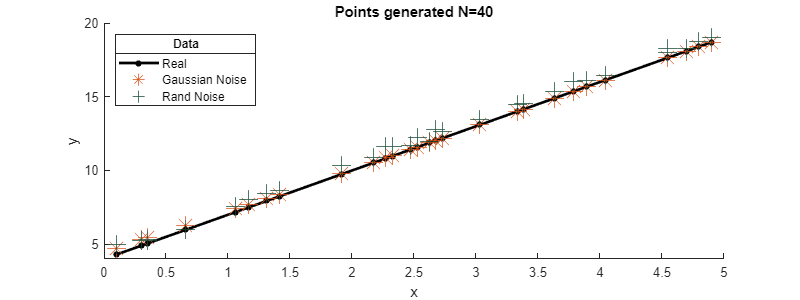

N = 30; rng(7);

xrand = zeros(N,1);
x     = linspace(0,5,100);  
xi    = randi(100,1,N);

for i=1:1:N; xrand(i) = x(xi(i)); end

y       = 3*xrand + 4;
ynoise  = y + (1/sqrt(2*pi)).*exp(-xrand.^2/2);
ynoise1 = y + 0.9*rand(N,1);

clf
figure(Position=[100 100 800 300]);
hold on
plot(xrand,y, '.-', MarkerSize=14, Color='black', LineWidth=2)
plot(xrand,ynoise, '*', MarkerSize=14)
plot(xrand,ynoise1, '+', MarkerSize=14, Color=[21/250 71/250 52/250])
leg = legend('Real', 'Gaussian Noise','Rand Noise','Location','northwest');
title(leg,'Data');
xlabel('x'); ylabel('y'); title('Points generated N=40')
hold off

### 2. Problem solution

Write the matrix $J$. Calculate the coefficients $a, \;b$ using the last equation and plot the measures and line getted in the same plane.

The equation (1) can be rewrite using residual vector $r$


$$r(x) = (ax_1+b-y_1, ax_2+b-y_2, \dots, ax_N+b-y_N)$$


then


$$\underset{a, b \in \mathbb{R}}{min} \sum_{i=0}^N r_i^2(a,b) =\underset{a, b \in \mathbb{R}}{min} ||r||_2^2$$


Jacobian


$$J = \left[\frac{\partial r_i}{\partial x_j}\right]_{ij}$$


with $i=1,\dots,N$ , $j=1,2$, and $x_1=a, \; x_2=b$. Then the Jacobian is


$$J = \pmatrix{
\frac{\partial r_1}{\partial a} & \frac{\partial r_1}{\partial b} \cr
\frac{\partial r_2}{\partial a} & \frac{\partial r_2}{\partial b} \cr
\vdots & \vdots \cr
\frac{\partial r_N}{\partial a} & \frac{\partial r_N}{\partial b} } =
\pmatrix{
x_1 & 1 \cr
x_2 & 1 \cr
\vdots & \vdots \cr 
x_{N-1} & 1  \cr
x_N & 1 
}$$


J = [xrand  ones(N,1)];
ab = J \ ynoise;            % A \ b %Ax = b  %'dividir a izquierda'
disp(['Optimal solution found by solving Gauss equations: a = ' num2str(ab(1)) ' b = ' num2str(ab(2))]);

Optimal solution found by solving Gauss equations: a = 2.9181 b = 4.3045


disp(['The residual error by solgin the Gauss equation is r = ' num2str(sum(ab(1)*xrand+ab(2)-ynoise))])

The residual error by solgin the Gauss equation is r = 1.3145e-13


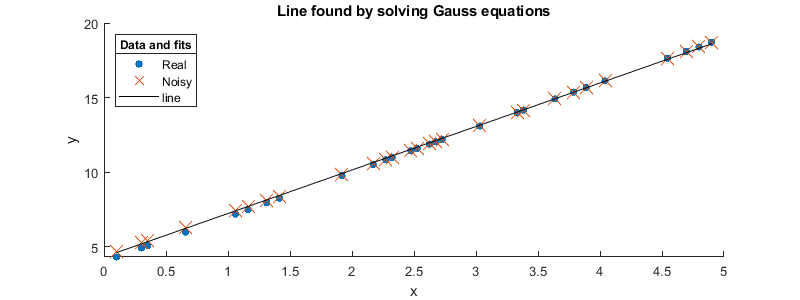

clf
figure(Position=[100 100 800 300]);
hold on
plot(xrand, y, '.', MarkerSize=14)
plot(xrand, ynoise, 'x', MarkerSize=14)
plot(xrand,ab(1)*xrand+ab(2), '-',Color='black')
leg = legend('Real', 'Noisy','line','Location','northwest');
title(leg,'Data and fits');
xlabel('x'); ylabel('y'); title('Line found by solving Gauss equations')
hold off

Let's verifyt the coefficients using CasADI.

import casadi.*

opti = casadi.Opti();
a_opt = opti.variable();
b_opt = opti.variable();
opti.minimize(norm(a_opt*xrand+b_opt-ynoise,2));

opti.solver('ipopt');

sol = opti.solve();

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:        3

Total number of variables............................:        2
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 6

aopt = sol.value(a_opt);
bopt = sol.value(b_opt);
disp(['Optimal solution found be CasADI: a = ' num2str(aopt) ' b = ' num2str(bopt)]);

Optimal solution found be CasADI: a = 2.9181 b = 4.3045


disp(['The residual error is by CasADI r = ' num2str(sum(aopt*xrand+bopt-ynoise))])

The residual error is by CasADI r = 7.9936e-15


disp(['CasADI - Gauss: 𐤃a = ' num2str(aopt-ab(1)) ' 𐤃b = ' num2str(bopt-ab(2))])

CasADI - Gauss: 𐤃a = -4.4409e-16 𐤃b = -2.6645e-15


Althouh both solutions have the same value of slope and $y$-intercept ($a,b$) with difference in the $15$-th decimal, the solution found by solving the Gauss equations has a smaller residual error then it is better. 

### 3. Atypical data

Introduce 3 atypical data in the measures $y$ and plot the new fitted line in the same plane.

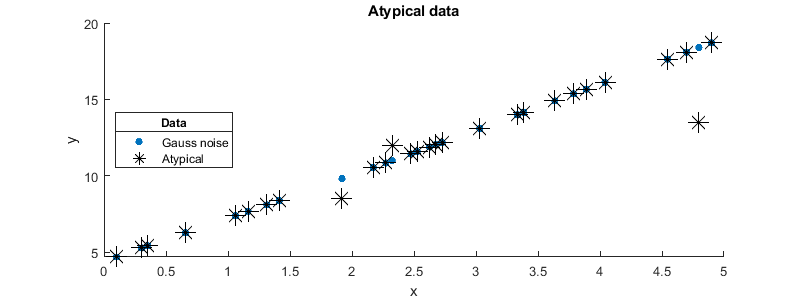

rng(123);
ynoise_atypical = ynoise;
ynoise_atypical(randi(N,3,1)) = ynoise_atypical(randi(N,3,1))+0.7*rand(1);

clf;
figure(Position=[100 100 800 300]);
hold on
plot(xrand, ynoise, '.', MarkerSize=14)
plot(xrand, ynoise_atypical, '*', MarkerSize=14 , Color='black')
leg = legend('Gauss noise', 'Atypical','Location','west');
title(leg,'Data');
xlabel('x'); ylabel('y'); title('Atypical data')
hold off

ab_atypical = J \ ynoise_atypical;            % A \ b %Ax = b  %'dividir a izquierda'
disp(['Optimal solution found by solving Gauss equations: a = ' num2str(ab_atypical(1)) ' b = ' num2str(ab_atypical(2))]);

Optimal solution found by solving Gauss equations: a = 2.755 b = 4.548


disp(['The residual error by solgin the Gauss equation is r = ' num2str(sum(ab_atypical(1)*xrand+ab_atypical(2)-ynoise_atypical))])

The residual error by solgin the Gauss equation is r = 9.9476e-14


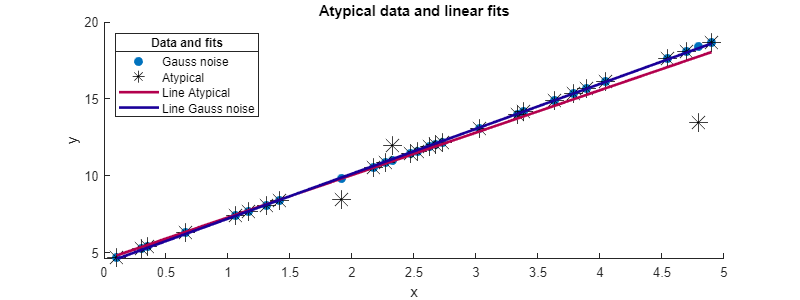

clf;
figure(Position=[100 100 800 300]);
hold on
plot(xrand, ynoise, '.', MarkerSize=20, DisplayName='Gauss noise')
plot(xrand, ynoise_atypical, '*', MarkerSize=14 , Color='black', DisplayName='Atypical')
plot(xrand, ab_atypical(1)*xrand+ab_atypical(2), '-', LineWidth=2, Color=[.7 .0 .3], DisplayName='Line Atypical')
plot(xrand,ab(1)*xrand+ab(2), '-', LineWidth=2, Color=[.1 0 .6], DisplayName='Line Gauss noise')
leg = legend('Location','northwest'); title(leg,'Data and fits');
xlabel('x'); ylabel('y'); title('Atypical data and linear fits')
hold off

The measures $y$ (with and without the atypical data) and the matrix $J$are necessary to the following point.

## 3. Linear Fitting in $L_1$

Now we are interesting to fit a line to the same measure set, but now using the following objective function

The objective function is not differentiable, then we are going to use width variables to get the following equivalent linear programming problem 

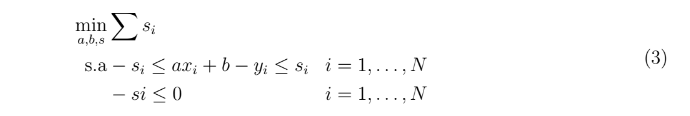

### 1. Problem reformulation, matrix A

In order to solve the previous linear programming problem use the MATLAB command `linprog`, to do this is necessary to write the problem as follows

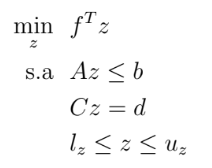

Write the matrix $A$ and the vectors $f,b$. Organize he variables as $z^T=[a,b, s_1,\dots ,s_N]$ Use the matrix $J$ from the previous exercise to define $A$.

Let's divide the problem in two


$$ax_i+b-y_i \leq s_i, \qquad  s_i \leq ax_i+b-y_i \\
ax_i+b-s_i \leq y_i  , \qquad   - ax_i-b+s_i\leq   - y_i\\
z_0 x_i+z_1- z_{i+2}\leq y_i, \qquad   - z_0 x_i - z_1 + z_{i+2} \leq   -y_i$$


for $i = 1, \dots , N$. Merging both conditions


$$z_0 x_i+z_1- z_{i+2}\leq y_i \\
-z_0 x_i - z_1 + z_{i+2} \leq   -y_i$$


In matricial form


$$\pmatrix{
x_1 & 1 & -1 &0 & 0 & \cdots & 0 \cr
x_2 & 1 &  0 & -1 & 0 & \cdots & \vdots \cr
\vdots & \vdots & 0 &0 & \ddots & \cdots & \vdots \cr
x_N & 1 &   0 &0 & 0 & \cdots & -1 \cr
-x_1 & -1 &   1 &0 & 0 & \cdots & 0 \cr
-x_2 & -1 &  0 & 1 & 0 & \cdots & 0 \cr
\vdots & \vdots &   0 &0 & \ddots & \cdots & 0 \cr
-x_N & -1 &  0 &0 & 0 & \cdots & 1 \cr}
\pmatrix{a \cr b \cr s_1 \cr s_2 \cr \vdots \cr s_{N-1} \cr s_{N}} \leq 
\pmatrix{y_1 \cr y_2 \cr \vdots \cr y_N\cr -y_1 \cr -y_2\cr \vdots \cr y_n}\\
A_{2N\times (N+2)} z_{(N+2) \times 1} \leq b_{2N\times 1}$$



$$A = \pmatrix{
J_{N\times 2} & -I_{N\times N}\cr
-J_{N\times 2} & I_{N\times N}}_{2N\times (N+2)} $$


Abig = zeros(2*N, N+2);
Abig(1:N,1:2) = J;         Abig(N+1:end,1:2) = -J;
Abig(1:N,3:end) = -eye(N); Abig(N+1:end,3:end) = eye(N);

f = [0; 0; ones(N,1)];   

Bbig = [ynoise; -ynoise]; Bbig_atypical = [ynoise_atypical; -ynoise_atypical]; 
SolBig = Abig \ Bbig;

max(ynoise_atypical - ynoise)

ans = 0.9816

SolBig_atypical = Abig \ Bbig_atypical;

disp(['Without atypical data: a=' num2str(SolBig_atypical(1)) ' b=' num2str(SolBig_atypical(2))])

Without atypical data: a=2.9173 b=4.4053


disp(['With atypical data a=' num2str(SolBig(1)) ' b=' num2str(SolBig(2))])

With atypical data a=2.9173 b=4.4053


From the equation (3), note that the vairable $s_i = ax_i+b-y_i$ and the product $f^T z$ must be a scalar. Then,


$$f= \pmatrix{0 \cr 0 \cr 1 \cr 1 \cr \vdots \cr 1}, \quad \rightarrow \quad f^T z = 
[ 0 , 0 , 1 , \cdots , 1]  \; \cdot \; 
\pmatrix{a \cr b \cr s_1 \cr \vdots \cr s_N} = s_1 + s_2 + \cdots + s_N = \sum_i^N s_i$$


note that the $i$-th component of the residual vector can be write in terms of $J$ as


$$ax_i+b-y_i =  \pmatrix{x_i & 1} \pmatrix{a \cr b} -y_i = 
J_{i}(a \; b)^T-y_i = (J(a \; b)^T-y)_i$$


respecto to the constraints, it can be write as follos using the matrix $J$ found in the previous point and the previous sustitution


$$-z' \leq J \pmatrix{a\cr b}-y\leq z', \quad \leftrightarrow \quad -z' -J \pmatrix{a\cr b}\leq -y\leq z'-J \pmatrix{a\cr b}$$


where $z=[a,b,s]$, $s=[s_1, s_2, \dots, s_N]$. For the components, since we are working in linear programming this constraint must be splitted in two

$-s-J \pmatrix{a\cr b}\leq -y \quad \leftrightarrow \quad s+J \pmatrix{a\cr b}\geq y\\
s-J \pmatrix{a\cr b} \geq -y \;\;\quad \leftrightarrow \quad -s+J \pmatrix{a\cr b}\leq y\\
\qquad -s \leq 0 \;\;\;\qquad \leftrightarrow \qquad  \qquad  s > 0$                                   (4)

where the last $0$ is a vector of $N+2$ components. Now let's contruct the matrix $A$ takink in aocunt the previous inequalities 


$$s_1 + x_1  a + b = z_3 + x_1  z_1 + z_2 \geq y_1\\
s_2 + x_2  a + b = z_4 + x_2 z_1 + z_2\geq y_2\\
s_3 + x_3  a + b = z_5 + x_3  z_1 + z_2\geq y_3\\
\qquad \qquad \qquad \vdots \\
s_{N} + x_N  a + b= z_{N+2} + x_N  z_1 + z_2 \geq y_N$$
   
$$\leftrightarrow$$
     
$$\pmatrix{
0 & 0 & 0 &0 & 0 & \cdots & 0 \cr
0 & 0 & 0 &0 & 0 & \cdots & 0 \cr
x_1 & 1 &   1 &0 & 0 & \cdots & 0 \cr
x_2 & 1 &   0 &1 & 0 & \cdots & 0 \cr
x_2 & 1 &   0 &0 & 1 & \cdots & 0 \cr
\vdots &  \vdots & \vdots & \vdots & \vdots & \ddots & \vdots \cr
x__N & 1 &   0 &0 & 0 & \cdots & 1 \cr}   \pmatrix{a \cr b \cr s_1 \cr s_2 \cr \vdots \cr s_{N-1} \cr s_{N}} \geq 
\pmatrix{0 \cr 0 \cr y_1 \cr y_2\cr y_3 \cr \vdots \cr y_n}$$


that can be write as $A_1 z \geq b$ with


$$z = \pmatrix{z_1 \cr z_2 \cr z_3 \cr \vdots \cr z_{N+2}} = \pmatrix{a \cr b \cr s_1 \cr \vdots \cr s_{N}}, \quad A_1 = \pmatrix{
0 & 0 & 0  &0 & 0 & \cdots & 0 \cr
0& 0   & 0 &0 & 0 & \cdots & 0 \cr
x_1 & 1   & 1 &0 & 0 & \cdots & 0 \cr
x_2 & 1   & 0 &1 & 0 & \cdots & 0 \cr
x_2 & 1   & 0 &0 & 1 & \cdots & 0 \cr
\vdots &   \vdots & \vdots & \vdots & \vdots & \ddots & \vdots \cr
x__N & 1  & 0 &0 & 0 & \cdots & 1 \cr}, \quad b= 
\pmatrix{0 \cr 0 \cr y_1 \cr y_2\cr y_3 \cr \vdots \cr y_n}$$


similarly the second constraint of (3) can be write as $A_2 z \leq b$


$$-s_1 + x_1  a + b = -z_3 + x_1  z_0 + z_1 \leq y_1\\
-s_2 + x_2  a + b = -z_4 + x_2 z_0 + z_1\leq y_2\\
-s_3 + x_3  a + b = -z_5 + x_3  z_0 + z_1\leq y_3\\
\qquad \qquad \qquad \vdots \\
-s_{N} + x_N  a + b= -z_{N+2} + x_N  z_0 + z_1 \leq y_N$$
   
$$\leftrightarrow$$
     
$$\pmatrix{
0 &   0 & 0 &0 & 0 & \cdots & 0 \cr
0&   0 & 0 &0 & 0 & \cdots & 0 \cr
x_1 & 1   & -1 &0 & 0 & \cdots & 0 \cr
x_2 & 1   & 0 &-1 & 0 & \cdots & 0 \cr
x_2 & 1   & 0 &0 & -1 & \cdots & 0 \cr
\vdots &  \vdots & \vdots & \vdots & \vdots & \ddots & \vdots \cr
x__N & 1  & 0 &0 & 0 & \cdots & -1 \cr}   \; \pmatrix{z_1 \cr z_2 \cr z_3 \cr z_4 \cr \vdots \cr z_{N+1} \cr z_{N+2}}  \leq  
\pmatrix{0 \cr 0 \cr y_1 \cr y_2\cr y_3 \cr \vdots \cr y_n}$$


with 


$$A_2 = \pmatrix{
 0 & 0 & 0 &0 & 0 & \cdots & 0 \cr
 0 & 0 & 0 &0 & 0 & \cdots & 0 \cr
x_1 & 1   & -1 &0 & 0 & \cdots & 0 \cr
x_2 & 1   & 0 &-1 & 0 & \cdots & 0 \cr
x_2 & 1   & 0 &0 & -1 & \cdots & 0 \cr
\vdots &   \vdots & \vdots & \vdots & \vdots & \ddots & \vdots \cr
x__N & 1 & 0 &0 & 0 & \cdots & -1 \cr} $$


and the final condition, all variables $s$ bigger than one can be write as $-s=- I z[2:end] \leq 0$ where the zero is the vector of zeros. 

Now implementing the matrixes $A_1, A_2$ and the vectors $b,f$ in the code

clf;
f = [0; 0; ones(N,1)];   
b = [0; 0; ynoise]; b_atypical = [0; 0; ynoise_atypical];

A1 = zeros(N+2); A1(3:end,1:2) = J; A1(3:end,3:end) = eye(N);
A2 = zeros(N+2); A2(3:end,1:2) = J; A2(3:end,3:end) = -eye(N);

### 2. Problem solution

Solve the problem using the $y$ measures from the previous exercise (with and without the atypical data) and plot the results over the $L_2$ results. Which norm has a better result?

**Without atypical data**

lb = zeros(N+2,1);
x =  linprog(f, Abig, Bbig, [], [], lb, []);

Optimal solution found.



x =  linprog(f, Abig, Bbig_atypical, [], [], lb, []);

Optimal solution found.




x_linprog =

     []



Problem is unbounded.



### 3.

Solve the problem with CasADi and compare the results.

opti3 = casadi.Opti();
z_opt3 = opti3.variable(N+2);

opti3.minimize(f'*z_opt3);

opti3.subject_to(A1*z_opt3 >= b); 
opti3.subject_to(A2*z_opt3 <= b); 
opti3.subject_to(-z_opt3(3:end) <= zeros(N,1)); 

opti3.solver('ipopt');
sol3 = opti3.solve();

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:     2078
Number of nonzeros in Lagrangian Hessian.............:        0

Total number of variables............................:       32
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:       94
        inequality constraints with only lower bounds:       32
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:       62

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

zopt3 = sol3.value(z_opt3);
zopt3'

ans =     2.9321    4.2577    0.1411    0.0068    0.0724    0.0101    0.0752    0.0647    0.0696    0.1411   -0.0000    0.0709    0.0265    0.0170    0.0640    0.1440    0.0148    0.0512    0.0417    0.0731    0.0615    0.1461    0.0477    0.0683    0.0244    0.0627    0.0512    0.1085    0.0665   -0.0000    0.0296    0.0730


%plot(zopt3(3:end),'-o')
%xlabel('i'); ylabel('s')
disp(['Optimal solution found: a = ' num2str(zopt3(1)) ' b = ' num2str(zopt3(2))]);

Optimal solution found: a = 2.9321 b = 4.2577


clf;
figure(Position=[100 100 900 400]);

subplot(1,2,1)
hold on
plot(xrand, ynoise, '.', MarkerSize=25, DisplayName='Gauss noise', Color='black')
plot(xrand, ab(1)*xrand+ab(2), '-', LineWidth=2, Color=[.7 .0 .3], DisplayName=['||_2: a=' num2str(ab(1)) ', b=' num2str(ab(2))])
plot(xrand,zopt3(1)*xrand+zopt3(2), '-', LineWidth=1, Color=[.1 0 .6], DisplayName=['||_1: a=' num2str(zopt3(1)) ', b=' num2str(zopt3(2))])
leg = legend('Location','northwest');
title(leg,'Data and Fits')
xlabel('x'); ylabel('y'); title('without atypical data', 'Interpreter','latex')
hold off
disp(['Residual sum: Σ si = ' num2str(sum(zopt3(3:end)))]);

Residual sum: Σ si = 1.8237


**Atypical data**

opti3_aty = casadi.Opti();
z_opt3_aty = opti3_aty.variable(N+2);

opti3_aty.minimize(f'*z_opt3_aty);

opti3_aty.subject_to(A1*z_opt3_aty >= b_atypical); 
opti3_aty.subject_to(A2*z_opt3_aty <= b_atypical); 
opti3_aty.subject_to(-z_opt3_aty(3:end) <= zeros(N,1)); 

opti3_aty.solver('ipopt');
sol3_aty = opti3_aty.solve();

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:     2078
Number of nonzeros in Lagrangian Hessian.............:        0

Total number of variables............................:       32
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:       94
        inequality constraints with only lower bounds:       32
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:       62

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 0

zopt3_aty = sol3_aty.value(z_opt3_aty);
zopt3_aty'

ans =     2.9181    4.2983    0.1054    0.0203    0.0827   -0.0000    0.1029    0.0680    0.0751    0.1054    0.0223    0.0770    0.0199    0.0327    1.4050    0.1075    0.0357    0.0739    0.0159    0.0821    0.0863    0.1069    0.0461    4.8185   -0.0000    0.0653    0.0739    0.0770    0.0706    0.0122    0.0238    0.9004


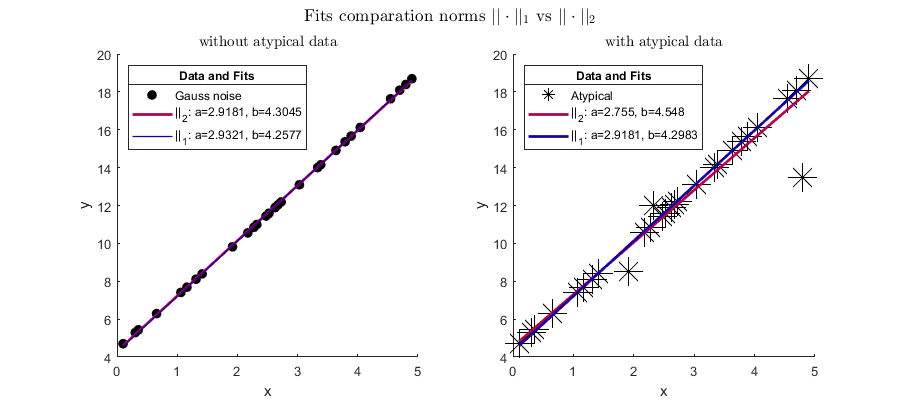

subplot(1,2,2)
hold on
%plot(xrand, ynoise, '.', MarkerSize=20, DisplayName='Gauss noise', Color='blue')
plot(xrand, ynoise_atypical, '*', MarkerSize=20, DisplayName='Atypical', Color='black')
plot(xrand, ab_atypical(1)*xrand+ab_atypical(2), '-', LineWidth=2, Color=[.7 .0 .3], DisplayName=['||_2: a=' num2str(ab_atypical(1)) ', b=' num2str(ab_atypical(2))])
plot(xrand,zopt3_aty (1)*xrand+zopt3_aty(2), '-', LineWidth=2, Color=[.1 0 .6], DisplayName=['||_1: a=' num2str(zopt3_aty(1)) ', b=' num2str(zopt3_aty(2))])
leg = legend('Location','northwest');
title(leg,'Data and Fits')
xlabel('x'); ylabel('y'); title('with atypical data', 'Interpreter','latex')
hold off
sgtitle('Fits comparation norms $||\cdot||_1$ vs $||\cdot||_2$',Interpreter='Latex');

disp(['RESIDUAL ERRORS' newline ...
    '- without atypical data:' newline ...
    '      Residual sum in ||_1: Σ si = ' num2str(sum(zopt3(3:end))) newline  ...
    '      residual error in ||_2 r = ' num2str(sum(ab(1)*xrand+ab(2)-ynoise)) newline ...
    '- with atypical data' newline ...
    '      Residual sum  in ||_1: Σ si = ' num2str(sum(zopt3_aty(3:end))) newline  ...
    '      residual error in ||_2  r = ' num2str(sum(ab_atypical(1)*xrand+ab_atypical(2)-ynoise_atypical)) newline  ])

RESIDUAL ERRORS
- without atypical data:
      Residual sum in ||_1: Σ si = 1.8237
      residual error in ||_2 r = 1.3145e-13
- with atypical data
      Residual sum  in ||_1: Σ si = 8.7128
      residual error in ||_2  r = 9.9476e-14



## 4. Integral Equation

Consider the following integral equation

### a) Exact solution

Find the exact solution (*Advice: *Interprete the operator $A:L^2(0,1)\to L^2(0,1)$ as the Laplace transform).

Let's take the solution to be an exponential function $x(t) = e^{at}$


$$\int_0^1 e^{st} e^{at} dt = \int_0^1 e^{(s+a)t} dt = \frac{1}{s+a} e^{(s+a)t}\Bigg|_0^1 = \frac{e^{s+a}-1}{s+a}  = \frac{e^{s+1}-1}{s+1} $$


then $a=1$and the solution is $x(x)=e^{t}$.

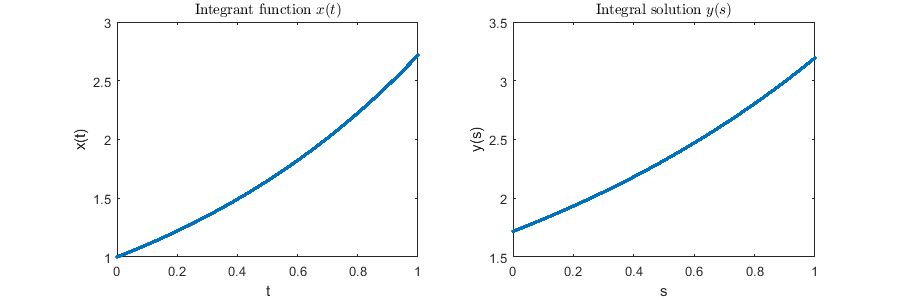

t = 0:0.001:1; 

clf
figure(Position=[10 10 900 300])
subplot(1,2,1)
plot(t,exp(t),'.');
xlabel('t'); ylabel('x(t)');
xlim([0 1]); %ylim([-14 5]);
title('Integrant function $x(t)$', Interpreter='latex');

subplot(1,2,2)
plot(t, (exp(t+1)-1)./(t+1), '.')
xlabel('s'); ylabel('y(s)');
title('Integral solution $y(s)$', Interpreter='latex');

### b) Problem Discretization

Use the Trapezoidal rule with an integer step $h=1/n$ and $s=ih$ and $i=1,\dots,n$ to get a linear system of equations.

Remembering the trapezoidal rule. Let $\{x_k\}$be a partition of $[0,1]$ such that $0=t_1<t_2<\cdots<t_{n-1}<t_n=1$and $\Delta t_k=\Delta t=1/n$be the length of the $k$-th subinterval


$$\int_a^b f(t) dx \approx \sum_{k=1}^{n-1}\frac{f(t_{k+1})+f(t_k)}{2} \Delta t_k$$


and applying it to the integral equation


$$\int_0^1 e^{st}x(t) dt \approx \sum_{k=1}^{n-1}\frac{e^{s t_{k+1}}x_{k+1}+e^{s t_k}x_k}{2} \cdot\frac{1}{n} = \frac{1}{2n} \sum_{k=1}^{n-1}(e^{st_{k+1}}x_{k+1}+e^{st_k}x_k )\\
= \frac{1}{2n} \left[ e^{st_{2}}x_{2}+e^{st_1}x_1  +  e^{st_{3}}x_{3}+e^{st_2}x_2  +  e^{st_{4}}x_{4}+e^{s t_3}x_3  + \cdots +  e^{st_{n}}x_{n}+e^{skt_{n-1}}x_{n-1} \right]\\
= \frac{1}{2n} \left[ e^{st_1}x_1  +2e^{st_{2}}x_{2}+ 2  e^{st_{3}}x_{3}+ 2  e^{st_{4}}x_{4}  + \cdots + 2e^{skt_{n-1}}x_{n-1} +  e^{st_{n}}x_{n}\right] = \frac{e^{s+1}-1}{s+1}$$


with $h=1/n$ and $s=ih$. Rewriting to the following system for any $s$. Then


$$y(s) =\int_0^1 e^{st}x(t) dt \approx  \frac{1}{2n} 
\pmatrix{ e^{st_1} & 2e^{st_{2}} & 2  e^{st_{3}} &  \cdots & 2e^{skt_{N-1}} & e^{st_{N}}} \cdot \pmatrix{x1 & x2 &  x_3 &\cdots & x_{n-1} & x_n} =  \frac{e^{s+1}-1}{s+1}$$


To build the system now let's evalute the previous expression to each $i$


$$s=0: \quad \frac{1}{2n } \pmatrix{ 1 & 2 & 2 &  \cdots & 2  & 1} \cdot \pmatrix{x_1 & x_2 &  x_3 &\cdots & x_{n -1} & x_n } =  e^1-1\\
s=h: \quad \frac{1}{2n } \pmatrix{ e^{ht_1} & 2e^{ht_{2}} & 2  e^{ht_{3}} &  \cdots & 2e^{ht_{n -1}} & e^{ht_{n }} } \cdot \pmatrix{x_1 & x_2 &  x_3 &\cdots & x_{n -1} & x_n } =  \frac{e^{h+1}-1}{h+1}\\
s=2h: \quad \frac{1}{2n } \pmatrix{ e^{2ht_1} & 2e^{2ht_{2}} & 2  e^{2ht_{3}} &  \cdots & 2e^{2ht_{n -1}} & e^{2ht_{n }} } \cdot \pmatrix{x_1 & x_2 &  x_3 &\cdots & x_{n -1} & x_n } =  \frac{e^{2h+1}-1}{2h+1}\\
\qquad \qquad \qquad \qquad \qquad \qquad \qquad \qquad \qquad \qquad \qquad \qquad \qquad \qquad \vdots \\
s=(n -1)h: \quad  \frac{1}{2n } \pmatrix{ e^{(n -1)ht_1} & 2e^{(n -1)ht_{2}} & 2  e^{(n -1)ht_{3}} &  \cdots & 2e^{(n -1)ht_{n -1}} & e^{(n -1)ht_{n }} } \cdot \pmatrix{x_1 & x_2 &  x_3 &\cdots & x_{n -1} & x_n } =  \frac{e^{(n-1)h+1}-1}{(n-1)h+1}\\
s=n h: \quad \frac{1}{2n } \pmatrix{ e^{nht_1} & 2e^{nht_{2}} & 2  e^{nht_{3}} &  \cdots & 2e^{nht_{n -1}} & e^{nht_{n }} } \cdot \pmatrix{x_1 & x_2 &  x_3 &\cdots & x_{n -1} & x_n } =  \frac{e^{nh+1}-1}{nh+1}$$


that can be write as $A x = b$ where


$$A_{(n\times n)} = \frac{1}{2n} \pmatrix{  e^{ht_1} & 2e^{ht_{2}} & 2  e^{ht_{3}} &  \cdots & 2e^{ht_{n -1}} & e^{ht_{n }}  \cr
 e^{2ht_1} & 2e^{2ht_{2}} & 2  e^{2ht_{3}} &  \cdots & 2e^{2ht_{n -1}} & e^{2ht_{n }}   \cr
\vdots &  \vdots &  \vdots & \cdots & \vdots & \vdots &  \cr
 e^{(n -1)ht_1} & 2e^{(n -1)ht_{2}} & 2  e^{(n -1)ht_{3}} &  \cdots & 2e^{(n -1)ht_{n -1}} & e^{(n -1)ht_{n }}  \cr 
e^{nht_1} & 2e^{nht_{2}} & 2  e^{nht_{3}} &  \cdots & 2e^{nht_{n -1}} & e^{nht_{n }}
}$$



$$x_{(n\times 1)} = \pmatrix{ x_1 \cr x_2 \cr \vdots \cr x_{n-1} \cr x_n}, \qquad b_{(n\times 1)} =\pmatrix{\frac{e^{h+1}-1}{h+1} \cr \frac{e^{2h+1}-1}{2h+1} \cr & \cr \frac{e^{(n-1)h+1}-1}{(n-1)h+1} \cr \frac{e^{nh+1}-1}{nh+1}
}$$


### c) Code Implementation

Find the solution to the linear system for $n=4,8,16,32$ and plot them. Point out the number condition of each linear system using the command `cond` on MATLAB.

#### Solution by Gauss eq

First, let's find the solution by solving the Gauss equations with the function `System(n,``α``)`

[time1, sol1, co1, M1, b1] = System(4,0);
[time2, sol2, co2, M2, b2] = System(8,0);
[time3, sol3, co3, M3, b3] = System(16,0);

[time4, sol4, co4, M4, b4] = System(32,0);

[time100, sol100, co100, M100, b100] = System(128,0);

disp(['cond n=4:   ' num2str(round(co1,2)) newline 'cond n=8:   ' num2str(co2) newline ...
      'cond n=16:  ' num2str(co3) newline 'cond n=32:  ' num2str(co4) newline 'cond n=128: ' num2str(co100)])

cond n=4:   23063.77
cond n=8:   9058044760132.311
cond n=16:  3.542464016391407e+17
cond n=32:  3.190396294578456e+18
cond n=128: 2.742725726910894e+19


where this variable `cond` is the conndition number for inversion, it measures the sensitivity of the solution of a system of linear equations to errors in the data. By default, Matlab calculates the 2-norm


$$ \text{cond }=\kappa(A) = ||A||_2\; ||A^{-1}||_2 $$


#### Solution by CasADI

Now let solve the problem with CasADI as the following optimization problem


$$\underset{x\in \mathbb{R}^n}{min} \quad ||Ax-b||^2_2$$


the function `SolCasADI(n,A,b) `is used here. 

x1 = SolCasADI(4, M1, b1);

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:       10

Total number of variables............................:        4
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 2

x2 = SolCasADI(8, M2, b2);

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:       36

Total number of variables............................:        8
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

x3 = SolCasADI(16, M3, b3);

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:      136

Total number of variables............................:       16
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 9

x4 = SolCasADI(32, M4, b4);

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:      528

Total number of variables............................:       32
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 1

x100 = SolCasADI(128, M100, b100);

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     8256

Total number of variables............................:      128
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 7

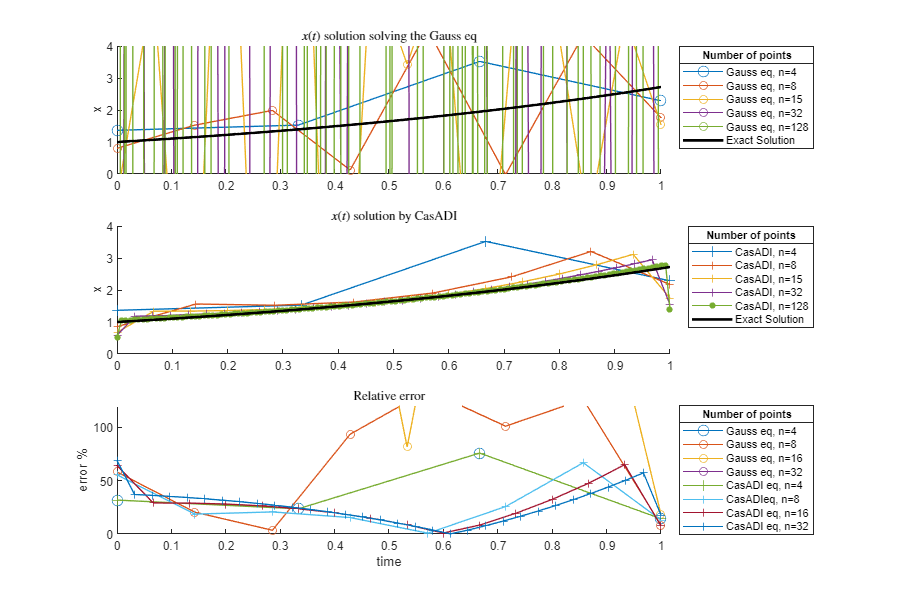

clf
figure(Position=[10 10 900 600])
subplot(3,1,1)
hold on
plot(time1, sol1','o-', DisplayName='Gauss eq, n=4',MarkerSize=8);
plot(time2, sol2','o-', DisplayName='Gauss eq, n=8');
plot(time3, sol3','o-', DisplayName='Gauss eq, n=15');
plot(time4, sol4','o-', DisplayName='Gauss eq, n=32');
plot(time100, sol100','o-', DisplayName='Gauss eq, n=128');
title('$x(t)$ solution solving the Gauss eq',Interpreter='latex')
plot(t, exp(t), Color='black',DisplayName='Exact Solution', LineWidth=2)
leg = legend('Location','northeastoutside');
title(leg,'Number of points')
ylim([0 4]);ylabel('x')
hold off

subplot(3,1,2)
hold on
plot(time1 , x1','+-', DisplayName='CasADI, n=4',MarkerSize=8);
plot(time2, x2','+-', DisplayName='CasADI, n=8');
plot(time3, x3','+-', DisplayName='CasADI, n=15');
plot(time4, x4','+-', DisplayName='CasADI, n=32');
plot(time100, x100','.-', DisplayName='CasADI, n=128', MarkerSize=14);
plot(t, exp(t), Color='black',DisplayName='Exact Solution', LineWidth=2)
xlim([0 1]); ylabel('x')

title('$x(t)$ solution by CasADI',Interpreter='latex')
leg = legend('Location','northeastoutside');
title(leg,'Number of points')
hold off
subplot(3,1,3)
hold on
plot(time1', 100*abs((sol1-exp( 0:1/3:1))/exp( 0:1/3:1)),'o-', DisplayName='Gauss eq, n=4',MarkerSize=8);
plot(time2', 100*abs((sol2-exp( 0:1/7:1))/exp( 0:1/7:1)),'o-', DisplayName='Gauss eq, n=8');
plot(time3', 100*abs((sol3-exp( 0:1/15:1))/exp( 0:1/15:1)),'o-', DisplayName='Gauss eq, n=16');
plot(time4', 100*abs((sol4-exp( 0:1/31:1))/exp( 0:1/31:1)),'o-', DisplayName='Gauss eq, n=32');

plot(time1', 100*abs((x1-exp( 0:1/3:1))/exp( 0:1/3:1)),'+-', DisplayName='CasADI eq, n=4',MarkerSize=8);
plot(time2', 100*abs((x2-exp( 0:1/7:1))/exp( 0:1/7:1)),'+-', DisplayName='CasADIeq, n=8');
plot(time3', 100*abs((x3-exp( 0:1/15:1))/exp( 0:1/15:1)),'+-', DisplayName='CasADI eq, n=16');
plot(time4', 100*abs((x4-exp( 0:1/31:1))/exp( 0:1/31:1)),'+-', DisplayName='CasADI eq, n=32');

title('Relative error ',Interpreter='latex')
leg = legend('Location','northeastoutside');
title(leg,'Number of points')
ylim([0 120]); xlabel('time'); ylabel('error %')
hold off

disp(['cond n=4:   ' num2str(round(co1,2)) newline 'cond n=8:   ' num2str(co2) newline ...
      'cond n=16:  ' num2str(co3) newline 'cond n=32:  ' num2str(co4) newline 'cond n=128: ' num2str(co100)])

cond n=4:   23063.77
cond n=8:   9058044760132.311
cond n=16:  3.542464016391407e+17
cond n=32:  3.190396294578456e+18
cond n=128: 2.742725726910894e+19


np = 2.^(1:1:8);
Solutions = zeros(8,2);
for i=np
    [s_casadi, s_Gausseq] = Error(0, i);
    Solutions(floor(log2(i)),:) = [s_casadi, s_Gausseq];
end

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:        3

Total number of variables............................:        2
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 1

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:      136

Total number of variables............................:       16
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 9

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:      528

Total number of variables............................:       32
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 1

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     2080

Total number of variables............................:       64
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 3

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     8256

Total number of variables............................:      128
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 7

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:    32896

Total number of variables............................:      256
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 1

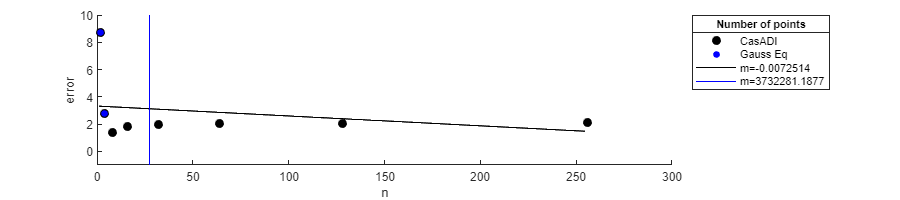

np_small = 1:2:256;
parameters = zeros(2,2);
parameters(1,:) = [ones(length(np),1)  np'] \ Solutions(:,1);
parameters(2,:) = [ones(length(np),1)  np'] \ Solutions(:,2);
clf
figure(Position=[10 10 900 200])
hold on
plot(np, Solutions(:,1), 'k.', MarkerSize=20, DisplayName='CasADI')
plot(np, Solutions(:,2), 'b.', MarkerSize=15, DisplayName='Gauss Eq')
plot(np_small, parameters(1,1)+np_small*+parameters(1,2), 'k-', DisplayName=['m=' num2str(parameters(1,2))]); 
plot(np_small, parameters(2,1)+np_small*parameters(2,2), 'b-', DisplayName=['m=' num2str(parameters(2,2))]); 
hold off
leg = legend('Location','northeastoutside');
title(leg,'Number of points')

ylim([-1 10])
xlabel('n'); ylabel('error')

Note that the first and last point are atypical data, this can be solved using the following matrix


$$A_{(n\times n)} = \frac{1}{n} \pmatrix{  e^{ht_1} & e^{ht_{2}} &   e^{ht_{3}} &  \cdots & e^{ht_{n -1}} & e^{ht_{n }}  \cr
 e^{2ht_1} & e^{2ht_{2}} &   e^{2ht_{3}} &  \cdots & e^{2ht_{n -1}} & e^{2ht_{n }}   \cr
\vdots &  \vdots &  \vdots & \cdots & \vdots & \vdots &  \cr
 e^{(n -1)ht_1} & e^{(n -1)ht_{2}} &   e^{(n -1)ht_{3}} &  \cdots & e^{(n -1)ht_{n -1}} & e^{(n -1)ht_{n }}  \cr 
e^{nht_1} & e^{nht_{2}} &  e^{nht_{3}} &  \cdots & e^{nht_{n -1}} & e^{nht_{n }}
}$$


It is also important to mention that the result given by solving the Gauss equations is counterintuitive, when the number of points $n$ increse the function starts to behave chaotically, the solution starts to oscillate drastically, then the bets solution in this case is when there are a few number of points.

In contrast, the solution with CasADI is different, the solution improves when $n$ increases then the best solution for this point is use CasADI library with high number of points. Furthermore, the relative error is plotted for both solution methods, here the result shows that CasADI has lower relative errors than by solving Gauss eq.

### d) Add Regularization

Solve the integral equation using the regularization method for each of the following parameters: i) $n=100, \; \alpha=0.2$, i) $n=100, \; \alpha=0.1$, and i) $n=100, \; \alpha=10^{-3}$. Plot the solutions.

#### Solution by Gauss eq

In this point, a regularization problem is added. The problem solution is found by solving the gauss equations 


$$x = (A+\alpha I)^{-1} b = (A+\alpha I) \; \backslash  \; b$$


[time_0,   sol_0,   co_0,   M_0,   b_0]   = System(100, 0);

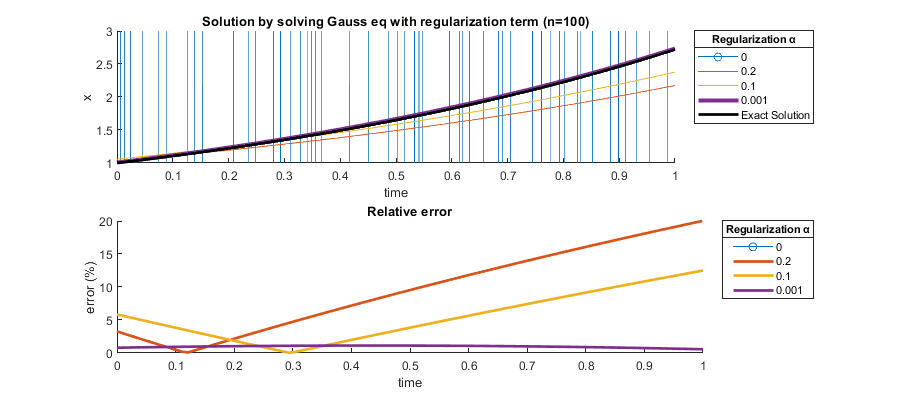

[time_i,   sol_i,   co_i,   M_i,   b_i]   = System(100, 0.2);
[time_ii,   sol_ii, co_ii,  M_ii,  b_ii]  = System(100, 0.1);
[time_iii, sol_iii, co_iii, M_iii, b_iii] = System(100, 0.001);

clf; 
figure(Position=[10 10 900 400])
subplot(2,1,1)
title('Solution by solving Gauss eq with regularization term (n=100)')
hold on
plot(time_0,   sol_0, '-o',DisplayName='0')
plot(time_i,   sol_i, DisplayName='0.2')
plot(time_ii,  sol_ii, DisplayName='0.1')
plot(time_iii, sol_iii, DisplayName='0.001', LineWidth=3)
plot(t,        exp(t), Color='black',DisplayName='Exact Solution', LineWidth=2)
leg = legend('Location','northeastoutside');
title(leg,'Regularization α')
xlabel('time'); ylabel('x'); ylim([1 3])
hold off
subplot(2,1,2)
title('Relative error')
hold on
plot(time_0,  100*abs((sol_0-exp(time_0)')./exp(time_0)'), '-o',DisplayName='0')
plot(time_i,  100*abs((sol_i-exp(time_i)')./exp(time_i)'), '-',  DisplayName='0.2', LineWidth=2)
plot(time_ii, 100*abs((sol_ii-exp(time_ii)')./exp(time_ii)'), '-', DisplayName='0.1', LineWidth=2)
plot(time_iii, 100*abs((sol_iii-exp(time_iii)')./exp(time_iii)'), '-', DisplayName='0.001', LineWidth=2)
leg = legend('Location','northeastoutside');
title(leg,'Regularization α')
xlabel('time'); ylabel('error (%)'); ylim([0 20])
hold off

disp(['The higher relative error for α=0.2 is   ' num2str(max(100*abs((sol_i-exp(time_i)')./exp(time_i)'))) newline ...
      'The higher relative error for α=0.1 is   ' num2str(max(100*abs((sol_ii-exp(time_ii)')./exp(time_ii)'))) newline ...
      'The higher relative error for α=0.001 is ' num2str(max(100*abs((sol_iii-exp(time_iii)')./exp(time_iii)')))])

The higher relative error for α=0.2 is   20.0283
The higher relative error for α=0.1 is   12.4936
The higher relative error for α=0.001 is 1.1288


disp(['cond n=100, α=0:     ' num2str(round(co_0,2)) newline 'cond n=100, α=0.2:   ' num2str(co_i) newline ...
      'cond n=100, α=0.01:  ' num2str(co_ii) newline 'cond n=100, α=0.001: ' num2str(co_iii)  ])

cond n=100, α=0:     1.855424207205099e+19
cond n=100, α=0.2:   7.7493
cond n=100, α=0.01:  14.5093
cond n=100, α=0.001: 1361.5892


In order to fix the condition of the matrix $A$ a regularization term is added. The result shows that as the regularization term decreases the solution improves, without the regularizaion term the solution is still unstable, and the best solution is when $\alpha = 0.001$ because the relative error is always smaller than $1.5  \; \%$.

#### Solution by CasADI

Now let's solve the problem, least squares, but modifying the matrix with a regularization parameter,$A = A+\alpha I$

x_casadi_0 = SolCasADI(100, M_0, b_0);

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     5050

Total number of variables............................:      100
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 5

x_casadi_i = SolCasADI(100, M_i, b_i);

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     5050

Total number of variables............................:      100
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 5

x_casadi_ii = SolCasADI(100, M_ii, b_ii);

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     5050

Total number of variables............................:      100
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 5

x_casadi_iii = SolCasADI(100, M_iii, b_iii);

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     5050

Total number of variables............................:      100
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 5

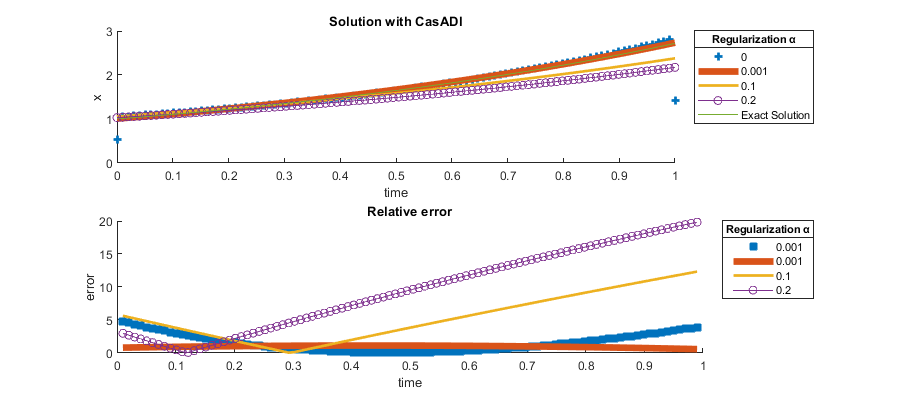

clf; 
figure(Position=[10 10 900 400])
subplot(211)
hold on
plot(time_0, x_casadi_0, '+',DisplayName='0', LineWidth=2)
plot(time_iii, x_casadi_iii, DisplayName='0.001', LineWidth=5)
plot(time_ii, x_casadi_ii, DisplayName='0.1', LineWidth=2)
plot(time_i, x_casadi_i, '-o', DisplayName='0.2')
plot(time_i, exp(time_i), DisplayName='Exact Solution')
leg = legend('Location','northeastoutside');
title(leg,'Regularization α')
ylabel('x'); xlabel('time'); title('Solution with CasADI')
hold off
subplot(212)
hold on
plot(time_0(2:end-1), 100*abs((x_casadi_0(2:end-1)-exp(time_0(2:end-1))')./exp(time_0(2:end-1))'), '+',DisplayName='0.001', LineWidth=5)    
plot(time_iii(2:end-1), 100*abs((x_casadi_iii(2:end-1)-exp(time_iii(2:end-1))')./exp(time_iii(2:end-1))'), DisplayName='0.001', LineWidth=5)
plot(time_ii(2:end-1), 100*abs((x_casadi_ii(2:end-1)-exp(time_ii(2:end-1))')./exp(time_ii(2:end-1))'), DisplayName='0.1', LineWidth=2)
plot(time_i(2:end-1), 100*abs((x_casadi_i(2:end-1)-exp(time_i(2:end-1))')./exp(time_i(2:end-1))'), '-o', DisplayName='0.2')
leg = legend('Location','northeastoutside');
title(leg,'Regularization α')
ylabel('error'); xlabel('time'); title('Relative error')
hold off

disp(['Maximum relative error ' num2str(max(100*abs((x_casadi_i(2:end-1)-exp(time_i(2:end-1))')./exp(time_i(2:end-1))')))])

Maximum relative error 19.8358


The relative error is ploted without the first and last point since CasADI calculate these points wrong, the value getted is the half of the real value and can be fixed by multiplying by 2 the first and last columns of the matrix $A$. Note that the solutions are the same since CasADI solve the problem correctly for 100 points, then the regularization term is not necessary when CasADI is used.

Solutions_regu = zeros(8,6);
for i=2.^(1:1:8)
    [s_casadi_i,   s_Gausseq_i]   = Error(0.2,   i);
    [s_casadi_ii,  s_Gausseq_ii]  = Error(0.1,   i);
    [s_casadi_iii, s_Gausseq_iii] = Error(0.001, i);
    Solutions_regu(floor(log2(i)),:) = [s_casadi_i, s_Gausseq_i, s_casadi_ii, s_Gausseq_ii, s_casadi_iii, s_Gausseq_iii, ];
end

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:        3

Total number of variables............................:        2
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 1

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:        3

Total number of variables............................:        2
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 1

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:        3

Total number of variables............................:        2
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 1

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:       10

Total number of variables............................:        4
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 2

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:       10

Total number of variables............................:        4
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 2

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:       10

Total number of variables............................:        4
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 2

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:       36

Total number of variables............................:        8
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:       36

Total number of variables............................:        8
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:       36

Total number of variables............................:        8
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 4

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:      136

Total number of variables............................:       16
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 9

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:      136

Total number of variables............................:       16
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 9

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:      136

Total number of variables............................:       16
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 9

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:      528

Total number of variables............................:       32
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 1

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:      528

Total number of variables............................:       32
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 1

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:      528

Total number of variables............................:       32
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 1

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     2080

Total number of variables............................:       64
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 3

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     2080

Total number of variables............................:       64
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 3

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     2080

Total number of variables............................:       64
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 3

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     8256

Total number of variables............................:      128
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 7

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     8256

Total number of variables............................:      128
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 7

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:     8256

Total number of variables............................:      128
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 7

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:    32896

Total number of variables............................:      256
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 1

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:    32896

Total number of variables............................:      256
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 1

This is Ipopt version 3.12.3, running with linear solver mumps.
NOTE: Other linear solvers might be more efficient (see Ipopt documentation).

Number of nonzeros in equality constraint Jacobian...:        0
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:    32896

Total number of variables............................:      256
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        0
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0 1

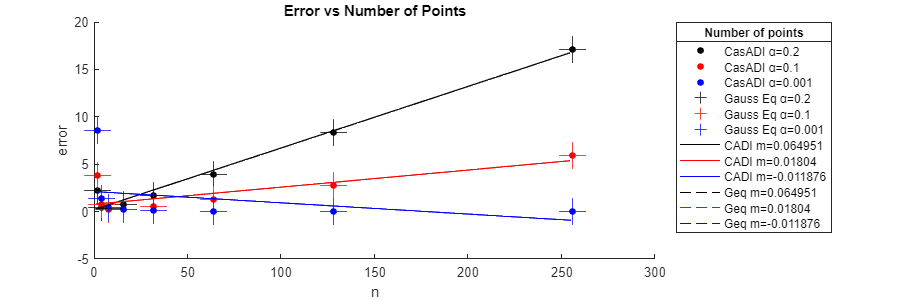

np_small = 1:2:256;
parameters = zeros(6,2);
for i=1:6
    parameters(i,:) = [ones(length(np),1)  np'] \ Solutions_regu(:,i);
end

figure(Position=[10 10 900 300])
hold on
plot(2.^(1:1:8), Solutions_regu(:,1), 'k.', MarkerSize=15, DisplayName='CasADI α=0.2')
plot(2.^(1:1:8), Solutions_regu(:,3), 'r.', MarkerSize=15, DisplayName='CasADI α=0.1')
plot(2.^(1:1:8), Solutions_regu(:,5), 'b.', MarkerSize=15, DisplayName='CasADI α=0.001')
plot(2.^(1:1:8), Solutions_regu(:,2), 'k+', MarkerSize=20, DisplayName='Gauss Eq α=0.2')
plot(2.^(1:1:8), Solutions_regu(:,4), 'r+', MarkerSize=20, DisplayName='Gauss Eq α=0.1')
plot(2.^(1:1:8), Solutions_regu(:,6), 'b+', MarkerSize=20, DisplayName='Gauss Eq α=0.001')

plot(np_small, parameters(1,1)+np_small*+parameters(1,2), 'k-', DisplayName=['CADI m=' num2str(parameters(1,2))]); 
plot(np_small, parameters(3,1)+np_small*+parameters(3,2), 'r-', DisplayName=['CADI m=' num2str(parameters(3,2))]); 
plot(np_small, parameters(5,1)+np_small*+parameters(5,2), 'b-', DisplayName=['CADI m=' num2str(parameters(5,2))]); 
plot(np_small, parameters(2,1)+np_small*+parameters(2,2), 'k--', DisplayName=['Geq m=' num2str(parameters(2,2))]); 
plot(np_small, parameters(4,1)+np_small*+parameters(4,2), 'r--', DisplayName=['Geq m=' num2str(parameters(4,2))]); 
plot(np_small, parameters(6,1)+np_small*+parameters(6,2), 'b--', DisplayName=['Geq m=' num2str(parameters(6,2))]); 

hold off
leg = legend('Location','northeastoutside');
title(leg,'Number of points')

%ylim([-1 10])
xlabel('n'); ylabel('error'); title('Error vs Number of Points')

parameters      

parameters =     0.2114    0.0650
    0.2114    0.0650
    0.7751    0.0180
    0.7751    0.0180
    2.1157   -0.0119
    2.1157   -0.0119


## Auxiliar Functions

function y=yfunc(s) 
    y = (exp(s+1)-1)./(s+1);
end

function [time, sol, co, M, b]=System(n, alfa)
    time = 0:1/(n-1):1;
    M = zeros(n,n);
    for i=1:n
        s = i*(1/n);
        
        v = exp(s*time); 
        v(2:end-1) = 2*v(2:end-1);
        
        M(i,:)= (1/(2*n))*v;
    end
    b   = yfunc((1:n)*(1/n))';
    M = M+alfa*eye(size(M));
    sol =  M \ b;
    co  = cond(M);
end

function x_int_opt=SolCasADI(n, M, b)
    opti_int = casadi.Opti();
    x_int = opti_int.variable(n);
    
    opti_int.minimize(norm(M*x_int-b,2)^2);
    
    opti_int.solver('ipopt');
    
    sol_int = opti_int.solve();
    x_int_opt = sol_int.value(x_int);
end

function [s_casadi, s_Gausseq] = Error(alpha, n)
	[time, sol, co, M, b] = System(n,alpha);
	x= SolCasADI(n, M, b);
	s_casadi  = sum((x'-exp(0:1/(n-1):1)).^2);
	s_Gausseq = sum((sol'-exp(0:1/(n-1):1)).^2);
end